%% --- CONFIGURACIÓN ---
clear; clc; close all;

% 1. Ruta a tu carpeta de datos.
dataDirectory = '/Users/minaal/Documents/TFG/BIJAY SOFTWARE SIMULATOR QKD/SatQuMA-main/SatQuMA-main/parse_datos/SenseTurbulencia_parsed/datos_procesados';

% 2. Elige los parámetros fijos para cada gráfica.
qberiFijoParaGraficaA = 0.005;
pecFijoParaGraficaB = 1e-7;

%% --- PASO 1: ENCONTRAR Y PROCESAR TODOS LOS ARCHIVOS ---

filePattern = fullfile(dataDirectory, '*.csv');
allFiles = dir(filePattern);

if isempty(allFiles)
    error('No se encontraron archivos .csv en la ruta especificada: %s', dataDirectory);
end

fprintf('Se encontraron %d archivos. Procesando...\n', length(allFiles));

Se encontraron 42 archivos. Procesando...



dataForFigA = containers.Map('KeyType', 'double', 'ValueType', 'any');
dataForFigB = containers.Map('KeyType', 'double', 'ValueType', 'any');

for i = 1:length(allFiles)
    filename = allFiles(i).name;
    filepath = fullfile(dataDirectory, filename);
    
    tokens = regexp(filename, 'Pec_([\d.e-]+)_QBERI_([\d.e-]+)', 'tokens');
    
    if isempty(tokens)
        fprintf('  - Omitiendo archivo (formato de nombre no reconocido): %s\n', filename);
        continue;
    end
    
    pecVal = str2double(tokens{1}{1});
    qberiVal = str2double(tokens{1}{2});
    
    try
        % Leer la tabla
        T = readtable(filepath, 'CommentStyle', '#');
        
        % --- NUEVO ENFOQUE: USAR ÍNDICES DE COLUMNA ---
        % Asumimos la siguiente estructura de columnas:
        % 1: dt (s), 2: ls (dB), 3: Pec, 4: QBERI, 5: SKL (b)
        
        % Depuración: Muestra los nombres de columna que MATLAB ve
        % disp(['Archivo: ', filename, ' | Nombres de columna: ', strjoin(T.Properties.VariableNames, ', ')]);
        
        % Extraer datos usando índices
        lossData = T{:, 2}; % Segunda columna
        sklData  = T{:, 5}; % Quinta columna

        % Agrupar por pérdida y encontrar el SKL máximo
        uniqueLoss = unique(lossData);
        maxSKL = zeros(length(uniqueLoss), 1);
        
        for j = 1:length(uniqueLoss)
            lossValue = uniqueLoss(j);
            % Encontrar el SKL máximo para este nivel de pérdida
            maxSKL(j) = max(sklData(lossData == lossValue));
        end
        
        % Crear una tabla con los datos optimizados
        optimizedTable = table(uniqueLoss, maxSKL, 'VariableNames', {'ls_dB', 'SKL_b'});
        
        % Almacenar la curva
        curveData = struct('pec', pecVal, 'qberi', qberiVal, 'data', optimizedTable);
        
        if ~isKey(dataForFigA, qberiVal)
            dataForFigA(qberiVal) = {};
        end
        dataForFigA(qberiVal) = [dataForFigA(qberiVal), {curveData}];
        
        if ~isKey(dataForFigB, pecVal)
            dataForFigB(pecVal) = {};
        end
        dataForFigB(pecVal) = [dataForFigB(pecVal), {curveData}];

    catch ME
        fprintf('  - Error procesando el archivo %s: %s\n', filename, ME.message);
    end
end

fprintf('Procesamiento de datos completado.\n\n');

Procesamiento de datos completado.





%% --- PASO 2: GENERAR GRÁFICA TIPO FIGURA 3a (vs Pec) ---

fprintf('Generando Gráfica 3a (vs Pec) para un QBERI fijo de %.3f\n', qberiFijoParaGraficaA);

Generando Gráfica 3a (vs Pec) para un QBERI fijo de 0.005


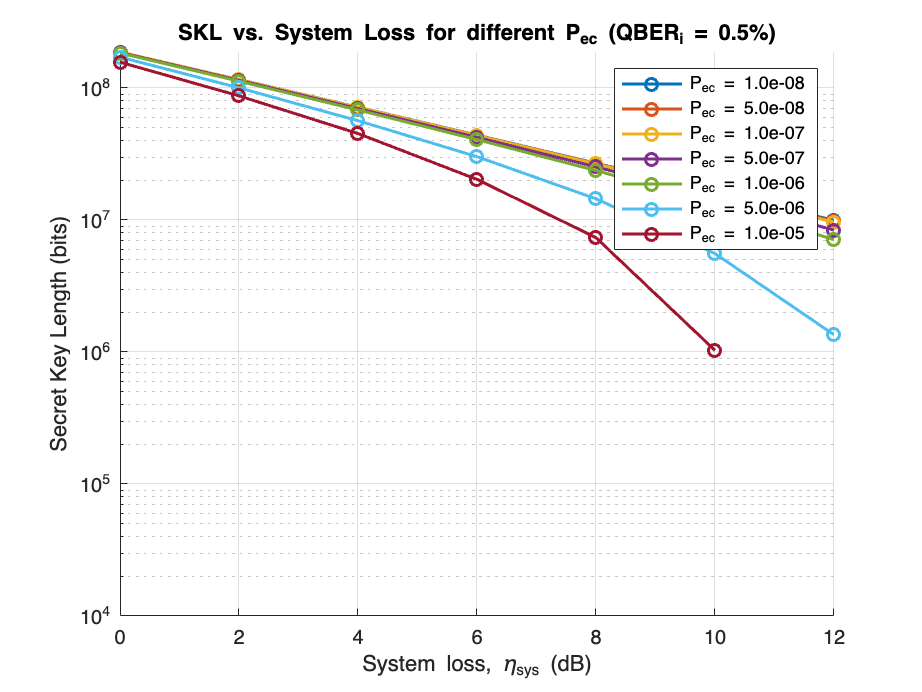

figure('Name', 'SKL vs System Loss (vs Pec)', 'NumberTitle', 'off');
hold on;
grid on;

if isKey(dataForFigA, qberiFijoParaGraficaA)
    curvesToPlot = dataForFigA(qberiFijoParaGraficaA);
    pecs = cellfun(@(c) c.pec, curvesToPlot);
    [~, sortIdx] = sort(pecs);
    
    for i = 1:length(sortIdx)
        curve = curvesToPlot{sortIdx(i)};
        data = curve.data;
        plotData = data(data.SKL_b > 0, :);
        
        if ~isempty(plotData)
            plot(plotData.ls_dB, plotData.SKL_b, '-o', 'LineWidth', 1.5, ...
                 'DisplayName', sprintf('P_{ec} = %.1e', curve.pec));
        end
    end
else
    warning('No se encontraron datos para graficar con QBERI = %.3f', qberiFijoParaGraficaA);
end

set(gca, 'YScale', 'log');
xlabel('System loss, \eta_{sys} (dB)');
ylabel('Secret Key Length (bits)');
title(sprintf('SKL vs. System Loss for different P_{ec} (QBER_i = %.1f%%)', qberiFijoParaGraficaA * 100));
legend('show', 'Location', 'northeast');
xlim([0, max(xlim)]); 
ylim([1e4, inf]);
hold off;



%% --- PASO 3: GENERAR GRÁFICA TIPO FIGURA 3b (vs QBERI) ---

fprintf('Generando Gráfica 3b (vs QBERI) para un Pec fijo de %.1e\n', pecFijoParaGraficaB);

Generando Gráfica 3b (vs QBERI) para un Pec fijo de 1.0e-07


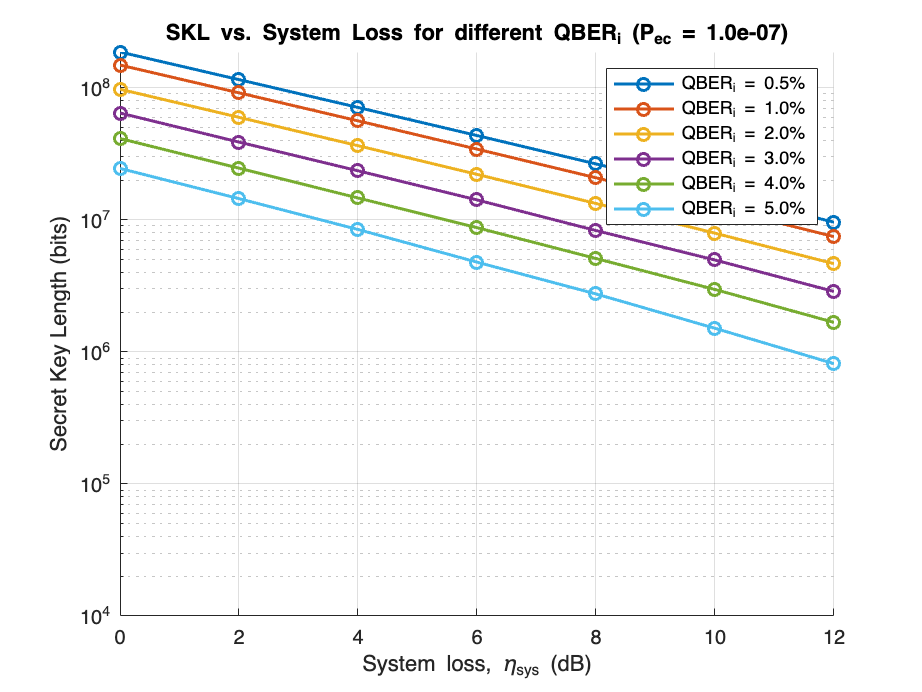

figure('Name', 'SKL vs System Loss (vs QBERI)', 'NumberTitle', 'off');
hold on;
grid on;

if isKey(dataForFigB, pecFijoParaGraficaB)
    curvesToPlot = dataForFigB(pecFijoParaGraficaB);
    qberis = cellfun(@(c) c.qberi, curvesToPlot);
    [~, sortIdx] = sort(qberis);
    
    for i = 1:length(sortIdx)
        curve = curvesToPlot{sortIdx(i)};
        data = curve.data;
        plotData = data(data.SKL_b > 0, :);
        
        if ~isempty(plotData)
            plot(plotData.ls_dB, plotData.SKL_b, '-o', 'LineWidth', 1.5, ...
                 'DisplayName', sprintf('QBER_i = %.1f%%', curve.qberi * 100));
        end
    end
else
    warning('No se encontraron datos para graficar con Pec = %.1e', pecFijoParaGraficaB);
end

set(gca, 'YScale', 'log');
xlabel('System loss, \eta_{sys} (dB)');
ylabel('Secret Key Length (bits)');
title(sprintf('SKL vs. System Loss for different QBER_i (P_{ec} = %.1e)', pecFijoParaGraficaB));
legend('show', 'Location', 'northeast');
xlim([0, max(xlim)]);
ylim([1e4, inf]);
hold off;